folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\"

folderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\"

fileName = ["Test 30.1","Test 30.2","Test 30.3","Test 30.4","Test 60.1","Test 60.2.2","Test 60.3","Test 60.4","Test 90.1","Test 90.2","Test 90.3","Test 90.4","Test 120.1","Test 120.2","Test 120.3","Test 120.4","Test 150.1","Test 150.2","Test 150.3","Test 150.4"]

fileName = 1×20 string array
    "Test 30.1"    "Test 30.2"    "Test 30.3"    "Test 30.4"    "Test 60.1"    "Test 60.2.2"    "Test 60.3"    "Test 60.4"    "Test 90.1"    "Test 90.2"    "Test 90.3"    "Test 90.4"    "Test 120.1"    "Test 120.2"    "Test 120.3"    "Test 120.4"    "Test 150.1"    "Test 150.2"    "Test 150.3"    "Test 150.4"


imageFolderPath ="C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\"

imageFolderPath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\"

figureWidth = 900; % Width in pixels
figureHeight = 500; % Height in pixels

% Set the figure size
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

for file = 1:length(fileName)
    filePath = fullfile(folderPath,fileName(file) + ".csv") 
    resultsBackwardsDirection= readtable(filePath,"VariableNamingRule","preserve")
    previousSpeed = 40;
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    aveargaePitch = zeros(1,length(resultsBackwardsDirection.("Current Pitch 1")));
    for i = 1:length(resultsBackwardsDirection.("Current Pitch 1"))
        aveargaePitch(i) = (resultsBackwardsDirection.("Current Pitch 1")(i) + resultsBackwardsDirection.("Current Pitch 2")(i))/2;
    end
     

## Pitch

    figure;
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 1"),'linewidth',1,'DisplayName','Rotor 1 Pitch','color',"#009DC4")
    hold on
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Target Pitch"),'r','linewidth',1,'DisplayName','Rotor 1 Target Pitch', 'color',"#f5b227")
    plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, resultsBackwardsDirection.("Current Pitch 2"),'linewidth',1,'DisplayName','Rotor 2 Pitch','color',"#D81B60")
    % plot((1:length(resultsBackwardsDirection.Timestamp)).*10e-3, aveargaePitch,'linewidth',1,'DisplayName','Average Pitch')
    ylim([-25,90])
    xlim([500,length(resultsBackwardsDirection.("Current Pitch 1"))*2.5/4].*10e-3)
    hold off
    ylabel('Pitch [°]');
    xlabel('Time [s]');
    title(sprintf('Change of Rotor Pitch Over Time at %d rpm with a %d° pitch', resultsBackwardsDirection.("Target Speed")(1), resultsBackwardsDirection.("Target Pitch")(1)));
    legend;

    set(gcf, 'Position', [100, 100, 1500, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Pitch Graph-" + fileName(file) + ".png")
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

## Loadcells

    resultsBackwardsDirection.("Load Cell 1") = -(resultsBackwardsDirection.("Load Cell 1") - resultsBackwardsDirection.("Load Cell 1")(1)).*0.0098;
    loadcell1 = rmmissing(resultsBackwardsDirection.("Load Cell 1"));
    loadcell1(isoutlier(resultsBackwardsDirection.("Load Cell 1"), 'mean')) = NaN;
    loadcell1 = fillmissing(loadcell1, 'linear');
    
    resultsBackwardsDirection.("Load Cell 2")  = -(resultsBackwardsDirection.("Load Cell 2")  - resultsBackwardsDirection.("Load Cell 2") (1)).*0.0098;
    loadcell2 = rmmissing(resultsBackwardsDirection.("Load Cell 2") );
    % loadcell2(isoutlier(resultsFrequencySweep.("Load Cell 2") , 'mean')) = NaN;
    loadcell2 = fillmissing(loadcell2, 'linear');
    
    resultsBackwardsDirection.("Load Cell 3")  = -((resultsBackwardsDirection.("Load Cell 3") ) - (resultsBackwardsDirection.("Load Cell 3") (1))).*0.0098.*0.9;
    loadcell3 = rmmissing(resultsBackwardsDirection.("Load Cell 3") );
    % loadcell3(isoutlier(resultsFrequencySweep.("Load Cell 3") , 'mean')) = NaN;
    loadcell3 = fillmissing(loadcell3, 'linear');
    
    resultsBackwardsDirection.("Load Cell 4")  = -((resultsBackwardsDirection.("Load Cell 4") ) - (resultsBackwardsDirection.("Load Cell 4") (1))).*0.0098.*0.8;
    loadcell4 = rmmissing(resultsBackwardsDirection.("Load Cell 4") );
    % loadcell4(isoutlier(resultsFrequencySweep.("Load Cell 4") , 'mean')) = NaN;
    loadcell4 = fillmissing(loadcell4, 'linear');
    
    % deltaThrust = (loadcell4+loadcell1)/2 - (loadcell3+loadcell2)/2

    aveargaeLoadcells = zeros(1,length(loadcell1));
    for i = 1:length(loadcell1)
        aveargaeLoadcells(i) = (loadcell1(i) + loadcell1(i) + loadcell1(i) + loadcell1(i));
    end
    figure;
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1,'DisplayName','Loadcell 1')
    hold on
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2)),loadcell2,'DisplayName','Loadcell 2')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell3)),loadcell3,'DisplayName','Loadcell 3')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell4)),loadcell4,'DisplayName','Loadcell 4')
    % plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'DisplayName','Combined Loadcells')
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    % xline(30)
    hold off
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Unfiltered Loadcell Readings for %d rpm with a %d° pitch', resultsBackwardsDirection.("Target Speed")(1), resultsBackwardsDirection.("Target Pitch")(1)));
    legend;
    TotalLoadcellScalled = interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcells)), aveargaeLoadcells, 1:length(aveargaePitch), 'linear')
    linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2))
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

    imageFilePath = fullfile(imageFolderPath,"Unfiltered Loadcell Readings-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1)),loadcell1)
    period = 0.44;
    fs = 1/period;   % Sampling Frequency
    nyquist_freq = fs/2 ;
    previousItterationPoint = 1
    

## FFT

    % speed = (resultsForwardDirection.("Current Speed")(floor(length(resultsForwardDirection.("Current Speed"))/2)));
    % rotor_freq = 135 * 2*pi/60/(2*pi);
    % period = 0.44;
    % fs = 1/period;   % Sampling Frequency
    % nyquist_freq = fs/2 ;
    % aliasing_freq = rotor_freq/nyquist_freq
    % if aliasing_freq < 2 && aliasing_freq > 1 && aliasing_freq < 3
    %     aliasing_freq = 2 - aliasing_freq;
    % else if aliasing_freq > 3
    %             aliasing_freq = 1-(aliasing_freq-3);
    % end
    % 
    % end
    % aliasing_freq
    %  mod(aliasing_freq,aliasing_freq)
    % plot_aliais = mod(aliasing_freq,aliasing_freq - mod(aliasing_freq/1,1))
    % 
    % L = length(aveargaeLoadcells);         % Length of the signal
    % Y = fft(aveargaeLoadcells);            % Perform FFT
    % 
    % 
    % P2 = abs(Y/L);                     % Two-sided spectrum
    % P1 = P2(1:floor(L/2)+1);           % Single-sided spectrum
    % P1(2:end-1) = 2*P1(2:end-1);       % Account for energy in both sides of spectrum
    % f = fs/L*(0:(L/2));                % Frequency axis
    % 
    % % abs(P2);
    % 
    % % Single-Sided Spectrum
    % figure;
    % plot(f, P1,"LineWidth",3);
    % xlim([0,f(end)])
    % title(sprintf('Single-Sided FFT of Combined Loadcell Output for %d rpm with a %d° pitch',135, resultsForwardDirection.("Target Pitch")(1)));
    % xlabel('Frequency (Hz)');
    % ylabel('Amplitude of Combined Loadcells');
    % xline(plot_aliais,'--r','linewidth',2);
    % % end
    % imageFilePath = fullfile(imageFolderPath,"FFT-" + fileName(file) + ".png");
    % dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    % print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    % close(gcf);
    % 
    % cutOffFrequency = 0.2;
    % nOrder = 4;
    % 
    % 
    [b,a] = butter(nOrder,cutOffFrequency/(fs/2));
    loadcell1Filtered = filtfilt(b,a,loadcell1);
    loadcell2Filtered = filtfilt(b,a,loadcell2);
    loadcell3Filtered = filtfilt(b,a,loadcell3);
    loadcell4Filtered = filtfilt(b,a,loadcell4);
    
    aveargaeLoadcellsFiltered = zeros(1,length(loadcell1Filtered));
    deltaThrust = (loadcell4Filtered+loadcell1Filtered) - (loadcell3Filtered+loadcell2Filtered);

    for i = 1:length(loadcell1Filtered)
        aveargaeLoadcellsFiltered(i) = (loadcell1Filtered(i) + loadcell2Filtered(i) + loadcell3Filtered(i) + loadcell4Filtered(i));
    end
    figure;
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell1Filtered)),loadcell1Filtered,'DisplayName','Loadcell 1')
    hold on
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell2Filtered)),loadcell2Filtered,'DisplayName','Loadcell 2')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell3Filtered)),loadcell3Filtered,'DisplayName','Loadcell 3')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(loadcell4Filtered)),loadcell4Filtered,'DisplayName','Loadcell 4')
    plot(linspace(0,length(resultsBackwardsDirection.Timestamp)*10e-3, length(deltaThrust)),deltaThrust,'r','linewidth',1, 'DisplayName','\Delta Thrust')
    % yline(mean(aveargaeLoadcellsFiltered(aveargaeLoadcellsFiltered > 1.3.*mean(aveargaeLoadcellsFiltered))),'-.b','DisplayName','Average Lift')
    hold off
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    ylabel('Lift [N]');
    xlabel('Time [s]');
    title(sprintf('Lift Generated at %d rpm with a %d° pitch', resultsBackwardsDirection.("Target Speed")(1),resultsBackwardsDirection.("Target Pitch")(1)));
    legend;
    
    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift Generated-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);
       

## Combined

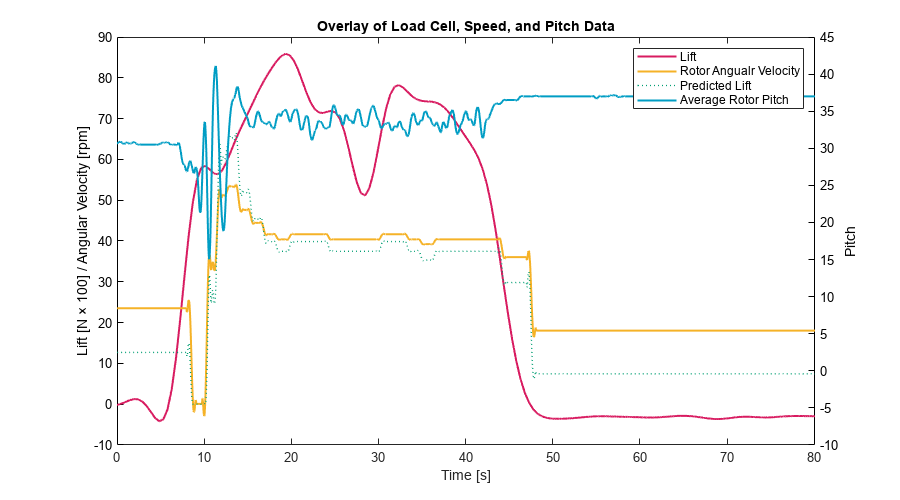

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 30.1.csv"

resultsBackwardsDirection = 8008×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:28:05         30             23.51             20               28                 34                -3            -4              5             -9     
    2024-10-15 14:28:05         30             23.51             20               28                 34 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 30.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4824    0.9648    1.4472    1.9296    2.4120    2.8945    3.3769    3.8593    4.3417    4.8241    5.3065    5.7889    6.2713    6.7537    7.2361    7.7186    8.2010    8.6834    9.1658    9.6482   10.1306   10.6130   11.0954   11.5778   12.0602   12.5427   13.0251   13.5075   13.9899   14.4723   14.9547   15.4371   15.9195   16.4019   16.8843   17.3667   17.8492   18.3316   18.8140   19.2964   19.7788   20.2612   20.7436   21.2260   21.7084   22.1908   22.6733   23.1557   23.6381


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 30.2.csv"

resultsBackwardsDirection = 9026×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:30:31         30             0.84              13               44                 82               -5             -3              2             -5     
    2024-10-15 14:30:31         30             0.84              13               44                 82 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 30.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4776    0.9551    1.4327    1.9103    2.3878    2.8654    3.3430    3.8205    4.2981    4.7757    5.2532    5.7308    6.2084    6.6859    7.1635    7.6411    8.1186    8.5962    9.0738    9.5513   10.0289   10.5065   10.9840   11.4616   11.9392   12.4167   12.8943   13.3719   13.8494   14.3270   14.8046   15.2821   15.7597   16.2372   16.7148   17.1924   17.6699   18.1475   18.6251   19.1026   19.5802   20.0578   20.5353   21.0129   21.4905   21.9680   22.4456   22.9232   23.4007


previousItterationPoint = 1

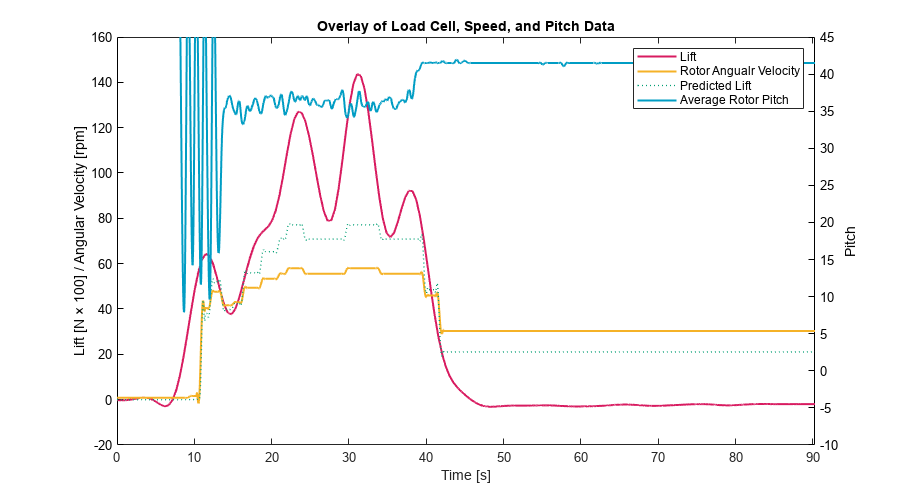

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 30.3.csv"

resultsBackwardsDirection = 5640×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:32:47         30             0.86              20               61                 77               -10             3              -7             4     
    2024-10-15 14:32:47         30             0.86              20               61                 77 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 30.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4739    0.9479    1.4218    1.8958    2.3697    2.8437    3.3176    3.7916    4.2655    4.7395    5.2134    5.6874    6.1613    6.6353    7.1092    7.5832    8.0571    8.5311    9.0050    9.4790    9.9529   10.4269   10.9008   11.3748   11.8487   12.3227   12.7966   13.2706   13.7445   14.2185   14.6924   15.1664   15.6403   16.1143   16.5882   17.0622   17.5361   18.0101   18.4840   18.9580   19.4319   19.9059   20.3798   20.8538   21.3277   21.8017   22.2756   22.7496   23.2235


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 30.4.csv"

resultsBackwardsDirection = 5392×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:34:29         30             24.24             20               30                 40               -21            19             -23            22     
    2024-10-15 14:34:29         30             24.24             20               30                 40 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 30.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4814    0.9629    1.4443    1.9257    2.4071    2.8886    3.3700    3.8514    4.3329    4.8143    5.2957    5.7771    6.2586    6.7400    7.2214    7.7029    8.1843    8.6657    9.1471    9.6286   10.1100   10.5914   11.0729   11.5543   12.0357   12.5171   12.9986   13.4800   13.9614   14.4429   14.9243   15.4057   15.8871   16.3686   16.8500   17.3314   17.8129   18.2943   18.7757   19.2571   19.7386   20.2200   20.7014   21.1829   21.6643   22.1457   22.6271   23.1086   23.5900


previousItterationPoint = 1

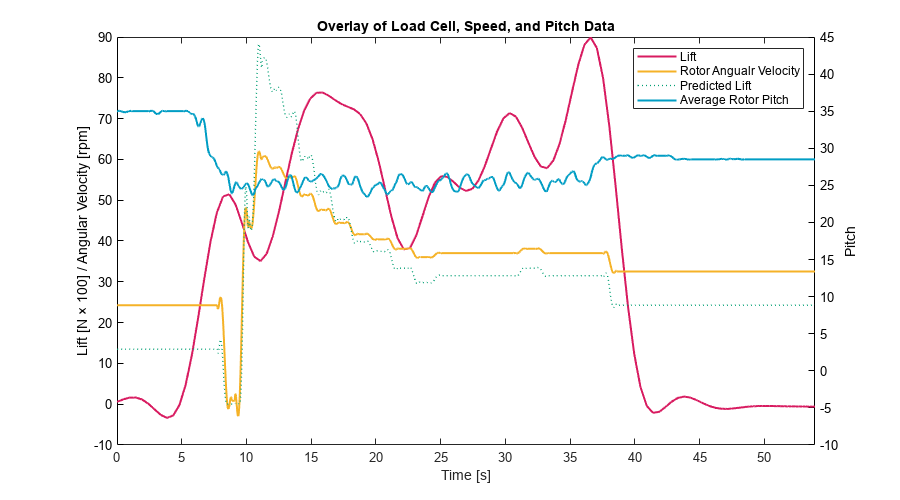

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 60.1.csv"

resultsBackwardsDirection = 6530×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:36:50         60             1.37              30               64                 70               -32            31             -34             32    
    2024-10-15 14:36:50         60             1.37              30               64                 70 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 60.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4732    0.9464    1.4196    1.8928    2.3659    2.8391    3.3123    3.7855    4.2587    4.7319    5.2051    5.6783    6.1514    6.6246    7.0978    7.5710    8.0442    8.5174    8.9906    9.4638    9.9370   10.4101   10.8833   11.3565   11.8297   12.3029   12.7761   13.2493   13.7225   14.1957   14.6688   15.1420   15.6152   16.0884   16.5616   17.0348   17.5080   17.9812   18.4543   18.9275   19.4007   19.8739   20.3471   20.8203   21.2935   21.7667   22.2399   22.7130   23.1862


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 60.2.2.csv"

resultsBackwardsDirection = 5832×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:51:33         60             16.67             27               49                 59                -1             -5              5            -10    
    2024-10-15 14:51:33         60             16.67             27               49                 59 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 60.2.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4780    0.9561    1.4341    1.9121    2.3902    2.8682    3.3462    3.8243    4.3023    4.7803    5.2584    5.7364    6.2144    6.6925    7.1705    7.6485    8.1266    8.6046    9.0826    9.5607   10.0387   10.5167   10.9948   11.4728   11.9508   12.4289   12.9069   13.3849   13.8630   14.3410   14.8190   15.2970   15.7751   16.2531   16.7311   17.2092   17.6872   18.1652   18.6433   19.1213   19.5993   20.0774   20.5554   21.0334   21.5115   21.9895   22.4675   22.9456   23.4236


previousItterationPoint = 1

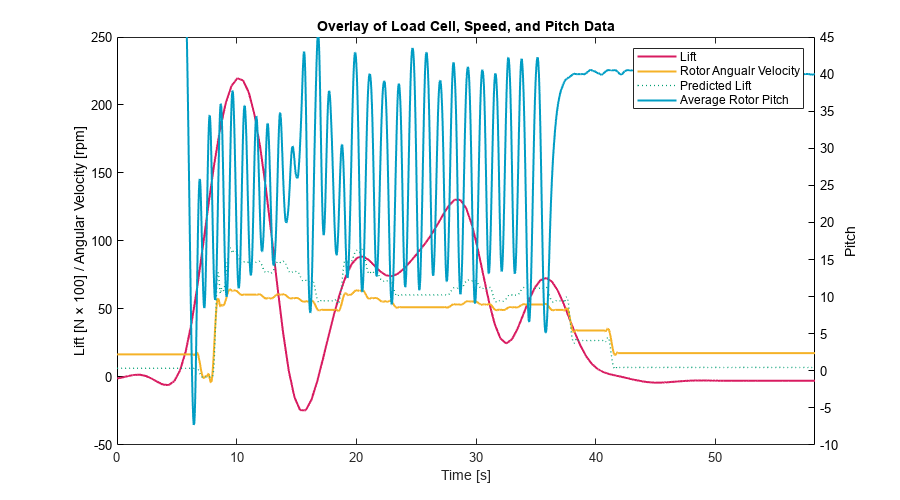

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 60.3.csv"

resultsBackwardsDirection = 5187×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:47:20         60             0.87              20               34                 -2               -10              7              4            -12    
    2024-10-15 14:47:20         60             0.87              20               34                 -2 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 60.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4803    0.9606    1.4408    1.9211    2.4014    2.8817    3.3619    3.8422    4.3225    4.8028    5.2831    5.7633    6.2436    6.7239    7.2042    7.6844    8.1647    8.6450    9.1253    9.6056   10.0858   10.5661   11.0464   11.5267   12.0069   12.4872   12.9675   13.4478   13.9281   14.4083   14.8886   15.3689   15.8492   16.3294   16.8097   17.2900   17.7703   18.2506   18.7308   19.2111   19.6914   20.1717   20.6519   21.1322   21.6125   22.0928   22.5731   23.0533   23.5336


previousItterationPoint = 1

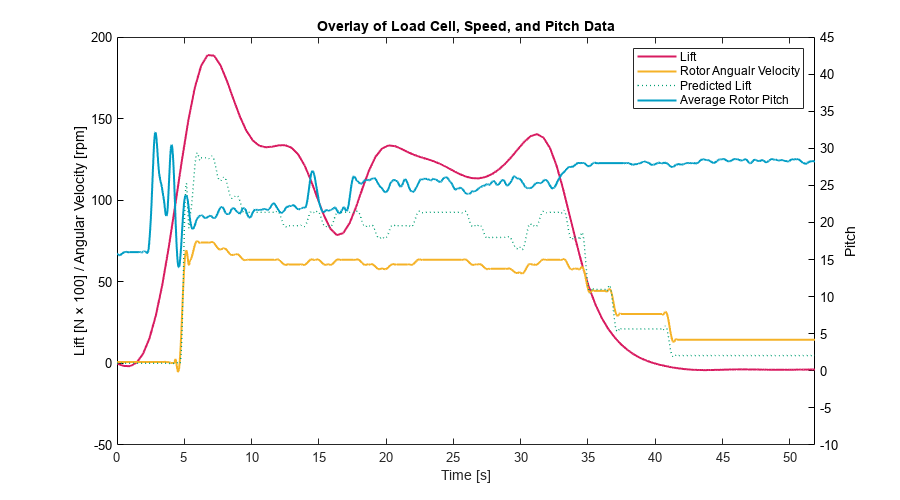

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 60.4.csv"

resultsBackwardsDirection = 5866×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:49:06         60              2.6              20               52                 24               -8              4              8             -14    
    2024-10-15 14:49:06         60              2.6              20               52                 24 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 60.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4808    0.9616    1.4425    1.9233    2.4041    2.8849    3.3657    3.8466    4.3274    4.8082    5.2890    5.7698    6.2507    6.7315    7.2123    7.6931    8.1739    8.6548    9.1356    9.6164   10.0972   10.5780   11.0589   11.5397   12.0205   12.5013   12.9821   13.4630   13.9438   14.4246   14.9054   15.3862   15.8670   16.3479   16.8287   17.3095   17.7903   18.2711   18.7520   19.2328   19.7136   20.1944   20.6752   21.1561   21.6369   22.1177   22.5985   23.0793   23.5602


previousItterationPoint = 1

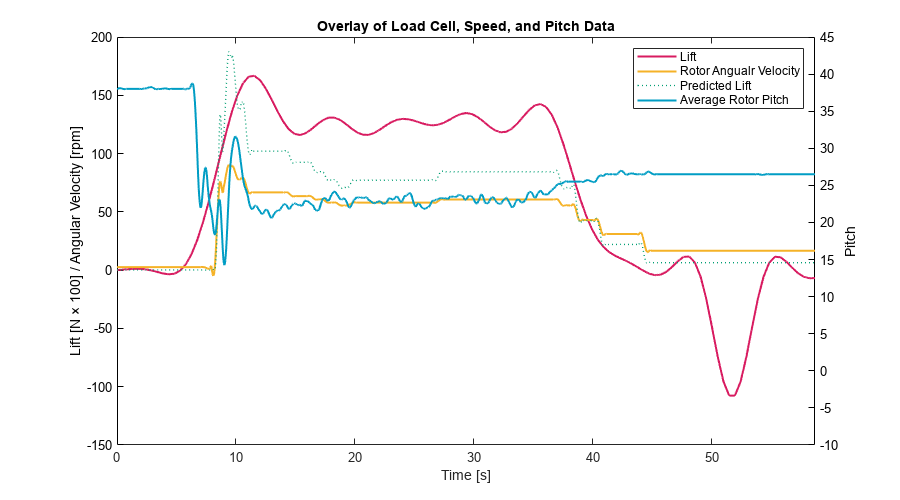

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 90.1.csv"

resultsBackwardsDirection = 6084×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:54:00         90             17.54             27               20                 31                -5             2              -1             -6    
    2024-10-15 14:54:00         90             17.54             27               20                 31 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 90.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4829    0.9657    1.4486    1.9314    2.4143    2.8971    3.3800    3.8629    4.3457    4.8286    5.3114    5.7943    6.2771    6.7600    7.2429    7.7257    8.2086    8.6914    9.1743    9.6571   10.1400   10.6229   11.1057   11.5886   12.0714   12.5543   13.0371   13.5200   14.0029   14.4857   14.9686   15.4514   15.9343   16.4171   16.9000   17.3829   17.8657   18.3486   18.8314   19.3143   19.7971   20.2800   20.7629   21.2457   21.7286   22.2114   22.6943   23.1771   23.6600


previousItterationPoint = 1

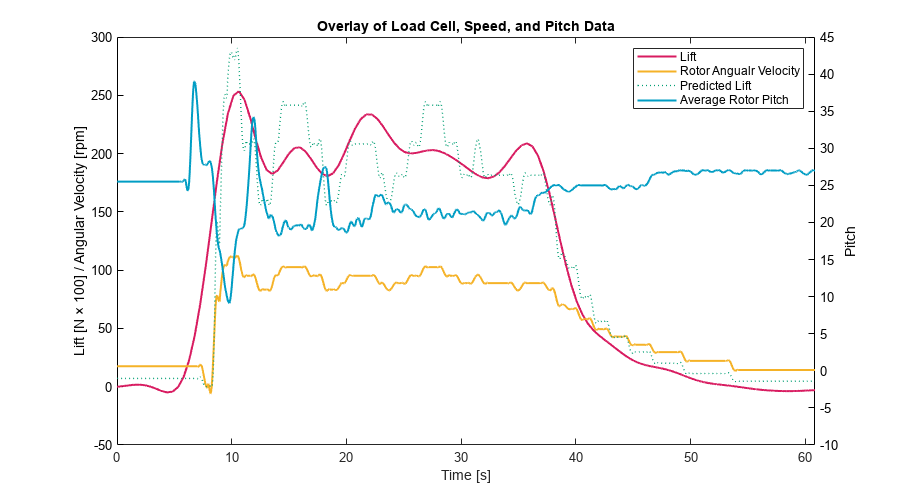

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 90.2.csv"

resultsBackwardsDirection = 6252×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:56:48         90             14.34             27               42                 42               -7              3              3             -10    
    2024-10-15 14:56:48         90             14.34             27               42                 42 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 90.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4809    0.9618    1.4428    1.9237    2.4046    2.8855    3.3665    3.8474    4.3283    4.8092    5.2902    5.7711    6.2520    6.7329    7.2138    7.6948    8.1757    8.6566    9.1375    9.6185   10.0994   10.5803   11.0612   11.5422   12.0231   12.5040   12.9849   13.4658   13.9468   14.4277   14.9086   15.3895   15.8705   16.3514   16.8323   17.3132   17.7942   18.2751   18.7560   19.2369   19.7178   20.1988   20.6797   21.1606   21.6415   22.1225   22.6034   23.0843   23.5652


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 90.3.csv"

resultsBackwardsDirection = 5480×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 14:59:17         90             0.96              13               26                 21               -18            17             -9               0    
    2024-10-15 14:59:17         90             0.96              13               26                 21 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 90.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4765    0.9530    1.4296    1.9061    2.3826    2.8591    3.3357    3.8122    4.2887    4.7652    5.2417    5.7183    6.1948    6.6713    7.1478    7.6243    8.1009    8.5774    9.0539    9.5304   10.0070   10.4835   10.9600   11.4365   11.9130   12.3896   12.8661   13.3426   13.8191   14.2957   14.7722   15.2487   15.7252   16.2017   16.6783   17.1548   17.6313   18.1078   18.5843   19.0609   19.5374   20.0139   20.4904   20.9670   21.4435   21.9200   22.3965   22.8730   23.3496


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 90.4.csv"

resultsBackwardsDirection = 5898×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:05:38         90             5.17              13               36                 37                 1            -8             18             -24    
    2024-10-15 15:05:38         90             5.17              13               36                 37 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 90.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4795    0.9590    1.4385    1.9180    2.3976    2.8771    3.3566    3.8361    4.3156    4.7951    5.2746    5.7541    6.2337    6.7132    7.1927    7.6722    8.1517    8.6312    9.1107    9.5902   10.0698   10.5493   11.0288   11.5083   11.9878   12.4673   12.9468   13.4263   13.9059   14.3854   14.8649   15.3444   15.8239   16.3034   16.7829   17.2624   17.7420   18.2215   18.7010   19.1805   19.6600   20.1395   20.6190   21.0985   21.5780   22.0576   22.5371   23.0166   23.4961


previousItterationPoint = 1

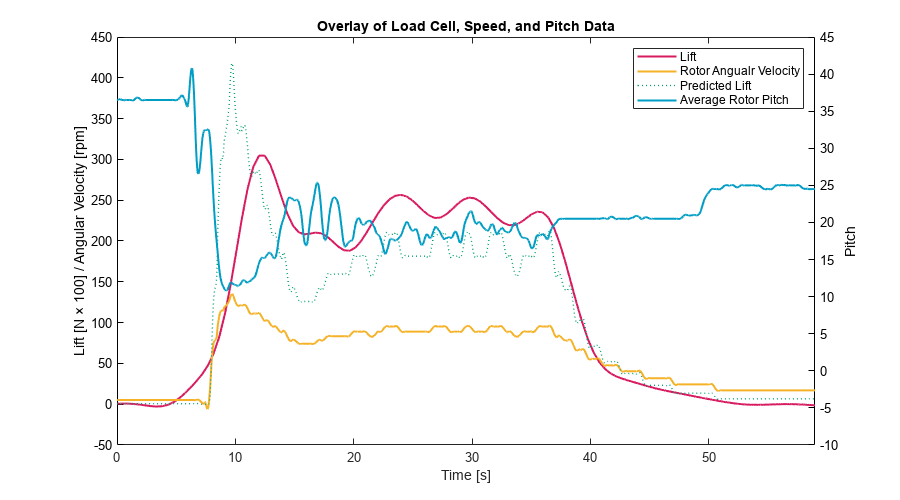

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 120.1.csv"

resultsBackwardsDirection = 7139×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:09:00        120             1.04              30               33                 42                 7            -14             26            -36    
    2024-10-15 15:09:00        120             1.04              30               33                 42 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 120.1.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4856    0.9713    1.4569    1.9426    2.4282    2.9139    3.3995    3.8852    4.3708    4.8565    5.3421    5.8278    6.3134    6.7990    7.2847    7.7703    8.2560    8.7416    9.2273    9.7129   10.1986   10.6842   11.1699   11.6555   12.1412   12.6268   13.1124   13.5981   14.0837   14.5694   15.0550   15.5407   16.0263   16.5120   16.9976   17.4833   17.9689   18.4546   18.9402   19.4259   19.9115   20.3971   20.8828   21.3684   21.8541   22.3397   22.8254   23.3110   23.7967


previousItterationPoint = 1

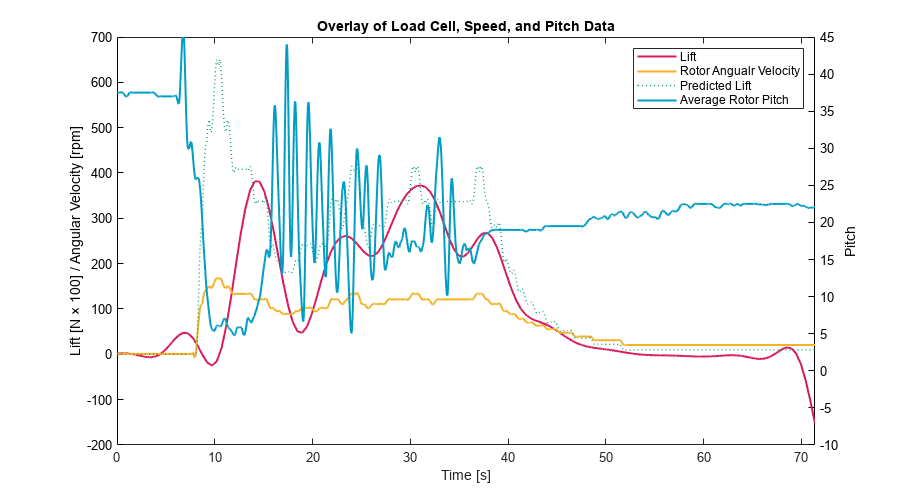

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 120.2.csv"

resultsBackwardsDirection = 6332×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:11:22        120             0.88              10               33                 91               -30            36             -31            21     
    2024-10-15 15:11:22        120             0.88              10               33                 91 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 120.2.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4834    0.9667    1.4501    1.9334    2.4168    2.9002    3.3835    3.8669    4.3502    4.8336    5.3169    5.8003    6.2837    6.7670    7.2504    7.7337    8.2171    8.7005    9.1838    9.6672   10.1505   10.6339   11.1173   11.6006   12.0840   12.5673   13.0507   13.5340   14.0174   14.5008   14.9841   15.4675   15.9508   16.4342   16.9176   17.4009   17.8843   18.3676   18.8510   19.3344   19.8177   20.3011   20.7844   21.2678   21.7511   22.2345   22.7179   23.2012   23.6846


previousItterationPoint = 1

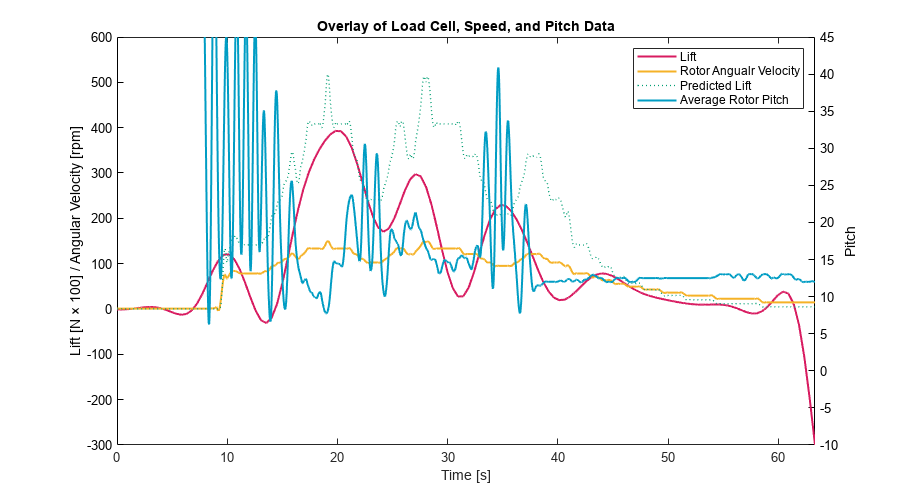

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 120.3.csv"

resultsBackwardsDirection = 6089×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:13:10        120             2.34              13               33                 16               -5              3              4             -15    
    2024-10-15 15:13:10        120             2.34              13               33                 16 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 120.3.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4871    0.9742    1.4614    1.9485    2.4356    2.9227    3.4098    3.8970    4.3841    4.8712    5.3583    5.8454    6.3326    6.8197    7.3068    7.7939    8.2810    8.7682    9.2553    9.7424   10.2295   10.7166   11.2038   11.6909   12.1780   12.6651   13.1522   13.6394   14.1265   14.6136   15.1007   15.5878   16.0750   16.5621   17.0492   17.5363   18.0234   18.5106   18.9977   19.4848   19.9719   20.4590   20.9462   21.4333   21.9204   22.4075   22.8946   23.3818   23.8689


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 120.4.csv"

resultsBackwardsDirection = 5122×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:31:14        120              4.9              13               17                 28               -20             19            -16             14    
    2024-10-15 15:31:14        120              4.9              13               17                 28 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 120.4.png"

TotalLoadcellScalled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans =          0    0.4832    0.9664    1.4496    1.9328    2.4160    2.8992    3.3825    3.8657    4.3489    4.8321    5.3153    5.7985    6.2817    6.7649    7.2481    7.7313    8.2145    8.6977    9.1809    9.6642   10.1474   10.6306   11.1138   11.5970   12.0802   12.5634   13.0466   13.5298   14.0130   14.4962   14.9794   15.4626   15.9458   16.4291   16.9123   17.3955   17.8787   18.3619   18.8451   19.3283   19.8115   20.2947   20.7779   21.2611   21.7443   22.2275   22.7108   23.1940   23.6772


previousItterationPoint = 1

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 150.1.csv"

resultsBackwardsDirection = 6087×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:33:46        150              0.9              10               26                 28               -26            25             -16            12     
    2024-10-15 15:33:46        150              0.9              10               26                 28 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 150.1.png"

TotalLoadcellScalled = 1×6087
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×127
         0    0.4831    0.9662    1.4493    1.9324    2.4155    2.8986    3.3817    3.8648    4.3479    4.8310    5.3140    5.7971    6.2802    6.7633    7.2464    7.7295    8.2126    8.6957    9.1788    9.6619   10.1450   10.6281   11.1112   11.5943   12.0774   12.5605   13.0436   13.5267   14.0098


previousItterationPoint = 1

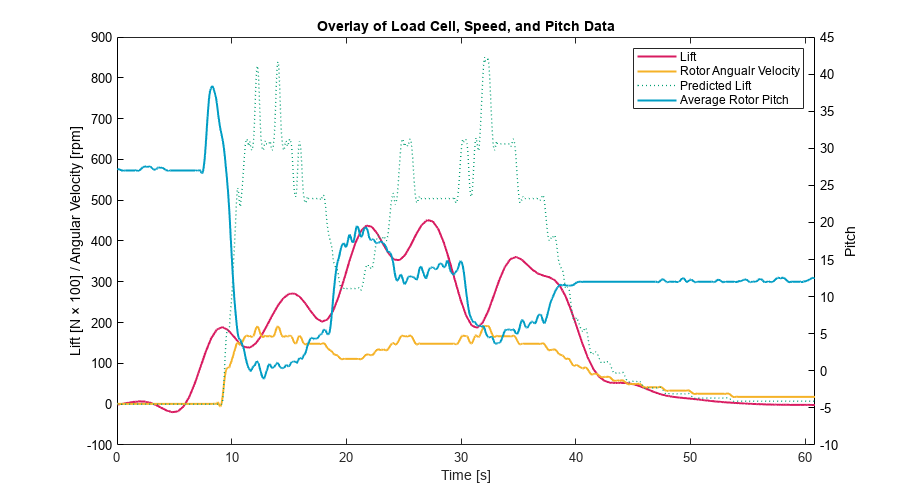

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 150.2.csv"

resultsBackwardsDirection = 6508×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:36:08        150             18.02             27               12                 -3               -33            34             -23             19    
    2024-10-15 15:36:08        150             18.02             27               12                 -3 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 150.2.png"

TotalLoadcellScalled = 1×6508
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×136
         0    0.4821    0.9641    1.4462    1.9283    2.4104    2.8924    3.3745    3.8566    4.3387    4.8207    5.3028    5.7849    6.2670    6.7490    7.2311    7.7132    8.1953    8.6773    9.1594    9.6415   10.1236   10.6056   11.0877   11.5698   12.0519   12.5339   13.0160   13.4981   13.9801


previousItterationPoint = 1

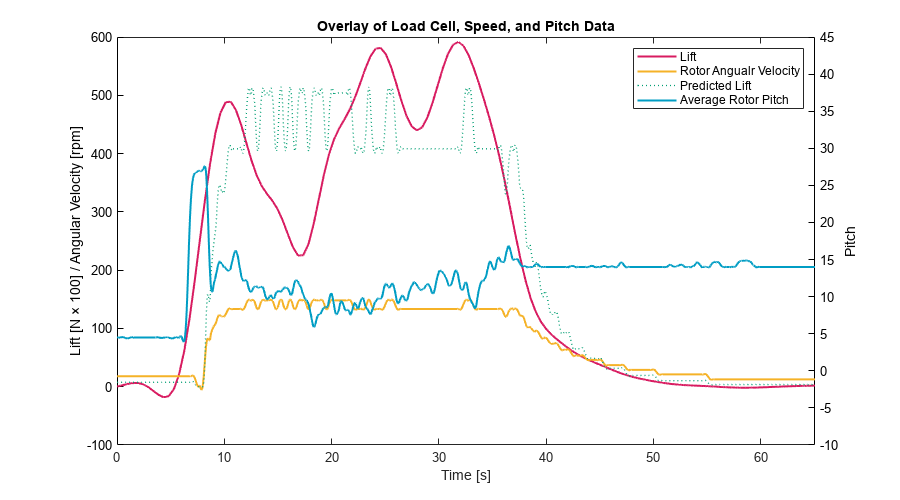

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 150.3.csv"

resultsBackwardsDirection = 5682×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:38:17        150             2.24              30               25                 26               -27             30            -30             23    
    2024-10-15 15:38:17        150             2.24              30               25                 26 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 150.3.png"

TotalLoadcellScalled = 1×5682
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×118
         0    0.4856    0.9713    1.4569    1.9426    2.4282    2.9138    3.3995    3.8851    4.3708    4.8564    5.3421    5.8277    6.3133    6.7990    7.2846    7.7703    8.2559    8.7415    9.2272    9.7128   10.1985   10.6841   11.1697   11.6554   12.1410   12.6267   13.1123   13.5979   14.0836


previousItterationPoint = 1

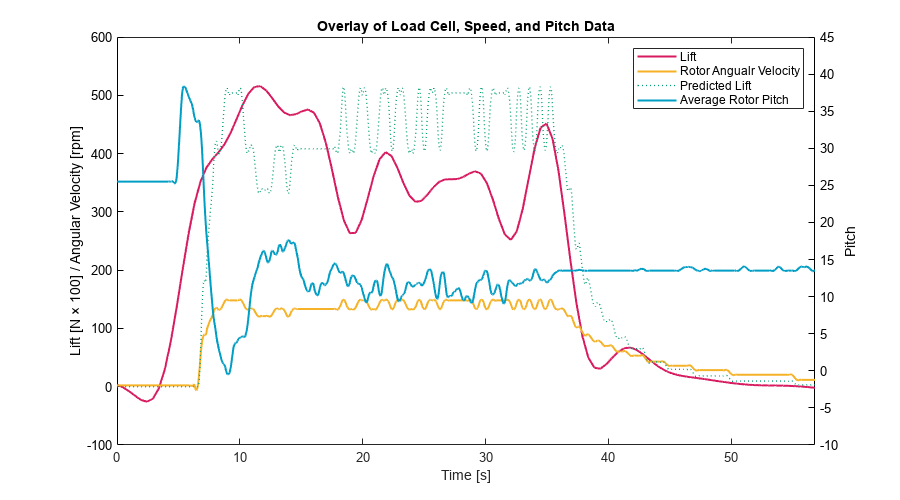

filePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Backwards Direction\Test 150.4.csv"

resultsBackwardsDirection = 5848×10 table
         Timestamp         Target Speed    Current Speed    Target Pitch    Current Pitch 1    Current Pitch 2    Load Cell 1    Load Cell 2    Load Cell 3    Load Cell 4
    ___________________    ____________    _____________    ____________    _______________    _______________    ___________    ___________    ___________    ___________

    2024-10-15 15:40:08        150             11.7              27               37                 26               -19             19            -18             12    
    2024-10-15 15:40:08        150             11.7              27               37                 26 

imageFilePath = "C:\Users\Rayde Kruger\OneDrive\Desktop\Skripsie\Expirment Data\Analysis\Backwards Direction Graphs\Pitch Graph-Test 150.4.png"

TotalLoadcellScalled = 1×5848
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 1×121
         0    0.4873    0.9747    1.4620    1.9493    2.4367    2.9240    3.4113    3.8987    4.3860    4.8733    5.3607    5.8480    6.3353    6.8227    7.3100    7.7973    8.2847    8.7720    9.2593    9.7467   10.2340   10.7213   11.2087   11.6960   12.1833   12.6707   13.1580   13.6453   14.1327


previousItterationPoint = 1

    predictedThrustFunction = @(x) 0.01805 .* (x .* pi/30).^2 + 0.002216 .* (x .* pi/30).^2/0.2625 .*sind(20);
    predictedThrust = predictedThrustFunction(sgolayfilt(resultsBackwardsDirection.("Current Speed"), 4, 111));
    
    clear alpha
    yyaxis left
    plot((1:length(aveargaePitch)).*10e-3, interp1(linspace(1, length(aveargaePitch), length(aveargaeLoadcellsFiltered)), aveargaeLoadcellsFiltered, 1:length(aveargaePitch), 'linear')*100,'color',"#D81B60", 'DisplayName', 'Lift', 'LineWidth', 1.5);
    hold on;
    plot((1:length(aveargaePitch)).*10e-3, sgolayfilt(resultsBackwardsDirection.("Current Speed"), 4, 111),'Linestyle','-', 'color',"#f5b227",'DisplayName', 'Rotor Angualr Velocity', 'LineWidth', 1.5);
    plot((1:length(aveargaePitch)).*10e-3,predictedThrust*100,'Linestyle',':','color',"#009E73", 'DisplayName', 'Predicted Lift', 'LineWidth', 1)
    alpha(0); % Set transparency for better visibility
    ylabel('Lift [N × 100] / Angular Velocity [rpm]');
    ax = gca;
    ax.YColor = 'k'; % Set color to black for consistency
    
    yyaxis right
    plot((1:length(aveargaePitch))*10e-3, sgolayfilt(aveargaePitch, 4, 111),'color',"#009DC4", 'DisplayName', 'Average Rotor Pitch', 'LineWidth', 1.5);
    alpha(0.2); % Set transparency
    ylabel('Pitch');
    ax.YColor = 'k'; % Set color to black for consistency
    ylim([-10,45])
        
    xlabel('Time [s]');
    title('Overlay of Load Cell, Speed, and Pitch Data');
    legend;
    xlim([0,length(resultsBackwardsDirection.Timestamp)*10e-3])
    % grid on;
    hold off;

    set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);
    imageFilePath = fullfile(imageFolderPath,"Lift, Pitch and Speed-" + fileName(file) + ".png");
    dpi = 300; % Set the desired resolution (300 DPI is a good quality setting)
    print(gcf, imageFilePath, '-dpng', ['-r' num2str(dpi)]);
    close(gcf);

end